% AAE 564 HW13 Problem 6
% Tomoki Koike
close all; clear all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
addpath(genpath("C:\Users\Tomo\Desktop\studies\2020-Fall\AAE564\matlab_simulink"))

% System requirements 
p = [-1, -1.22, -1.5, -2, -2.3, -2.7];

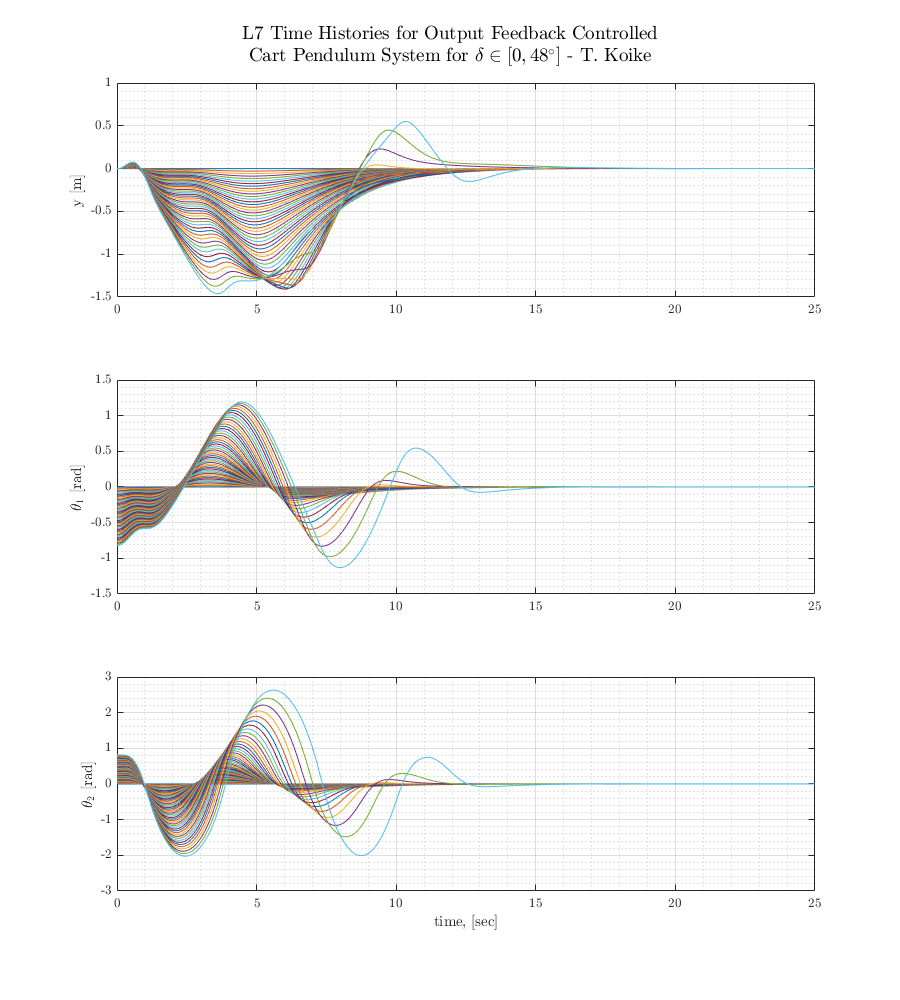

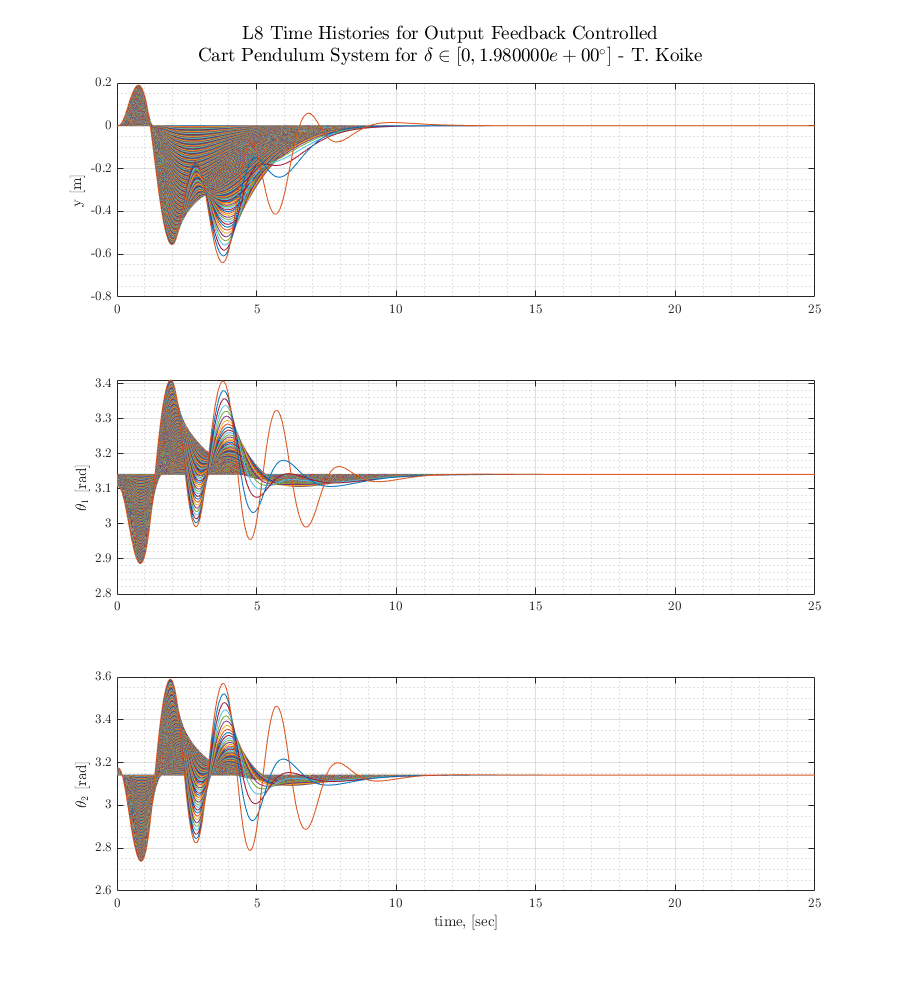

global m l g ye theta1e theta2e
warning('off');
param_combo = ["L7","L8"]; %["L7","L8"]
for i = 1:numel(param_combo)
    define_params(param_combo(i));
    xe = trim('db_pend_cart_lin');
    [A, B, C, D] = linmod('db_pend_cart_lin',xe);
    lin_sys(i).Amat = A;
    lin_sys(i).Bmat = B;
    lin_sys(i).Cmat = C;
    lin_sys(i).Dmat = D;
    
    % Compute the gains
    K    = -place(A, B, p);
    lin_sys(i).K = K;
    L    = -place(A', C', p)';
    lin_sys(i).L = L;
    
    % Output feedback matrices 
    Ac = A + B*K + L*C;
    Bc = -L;
    [B_rows, B_cols] = size(Bc);
    Cc = K;
    [C_rows, C_cols] = size(Cc);
    Dc = zeros(C_rows, B_cols);
    ICc = zeros(B_rows, 1);
    
    % Plotting 
    % Initialize figure
    fig = figure('Renderer',"painters", 'Position', [10 10 900 1000]); 
    delta_max = "0";
    inc_history = [];
    while true
        % delta = linspace(0,deg2rad(str2double(delta_max(i))),50)
        delta = str2double(delta_max);
        % Initial conditions 
        dyi = 0; 
        u = 0; 
        yi = ye + dyi; 
        theta1i = theta1e - deg2rad(delta); 
        theta2i = theta2e + deg2rad(delta);
        IC_ss = [yi, theta1i, theta2i, 0, 0, 0];
        
        % Simulate 
        simout = sim('db_pend_cart_lin_outputFeedback');
        lin_sys(i).simout = simout;   
        
        % Plot 
        time = simout.tout;
        data = simout.res.signals.values;
        y = data(:,1);
        theta1 = data(:,2);
        theta2 = data(:,3);
        
        if i == 1
            if abs(theta1(end)-theta1e) > 0.1 || abs(theta2(end)-theta2e) > 0.1
                break;
            elseif abs(theta1(end)-theta1e) > 0.08 || abs(theta2(end)-theta2e) > 0.08
                inc = 0.01;
            elseif abs(theta1(end)-theta1e) > 0.05 || abs(theta2(end)-theta2e) > 0.05
                inc = 0.1;
            elseif abs(theta1(end)-theta1e) > 0.01 || abs(theta2(end)-theta2e) > 0.01
                inc = 0.5;
            elseif abs(theta1(end)-theta1e) > 0.001 || abs(theta2(end)-theta2e) > 0.001
                inc = 0.8;
            else
                inc = 1;
            end
        else
            if abs(theta1(end)-theta1e) > 0.1 || abs(theta2(end)-theta2e) > 0.1
                break;
            else
                inc = 0.01;
            end
        end
        
        subplot(3,1,1) 
        grid on; grid minor; box on;
        plot(time,y)
        hold on; grid on; grid minor; box on;
        ylabel('y [m]')
        subplot(3,1,2)
        grid on; grid minor; box on;
        plot(time,theta1)
        hold on; grid on; grid minor; box on; 
        ylabel('$\theta_1$ [rad]')
        subplot(3,1,3)
        grid on; grid minor; box on;
        plot(time,theta2)
        hold on; grid on; grid minor; box on;
        ylabel('$\theta_2$ [rad]')
        
        delta_max = num2str(str2double(delta_max) + inc);
        inc_history = [inc_history, inc];
    end
    hold off;
    xlabel('time, [sec]')
    line1 = param_combo(i)+' Time Histories for Output Feedback Controlled';
    delta_char = compose("%d", str2double(delta_max));
    line2 = 'Cart Pendulum System for $\delta\in[0,'+delta_char+'^{\circ}]$ - T. Koike';
    title_string = {line1,line2};
    sgtitle(title_string)
    saveas(fig, 'p6_'+param_combo(i)+'.png');
end

function define_params(L)
    % Function to define parameters
    global m l g ye theta1e theta2e
    if L == "L1"
        m = [2,1,1]; l = [1,1]; g = 1; % P1
        ye = 0; theta1e = 0; theta2e = 0; % E1
    elseif L == "L2"
        m = [2,1,1]; l = [1,1]; g = 1; % P1
        ye = 0; theta1e = pi; theta2e = pi; % E2 
    elseif L == "L3"
        m = [2,1,1]; l = [1,0.99]; g = 1; % P2
        ye = 0; theta1e = 0; theta2e = 0; % E1
    elseif L == "L4"
        m = [2,1,1]; l = [1,0.99]; g = 1; % P2
        ye = 0; theta1e = pi; theta2e = pi; % E2 
    elseif L == "L5"
        m = [2,1,0.5]; l = [1,1]; g = 1; % P3
        ye = 0; theta1e = 0; theta2e = 0; % E1
    elseif L == "L6"
        m = [2,1,0.5]; l = [1,1]; g = 1; % P3
        ye = 0; theta1e = pi; theta2e = pi; % E2 
    elseif L == "L7"
        m = [2,1,1]; l = [1,0.5]; g = 1; % P4
        ye = 0; theta1e = 0; theta2e = 0; % E1
    elseif L == "L8"
        m = [2,1,1]; l = [1,0.5]; g = 1; % P4
        ye = 0; theta1e = pi; theta2e = pi; % E2
    else
        print('error: did not match any')
    end
end